clc; clear; close all;

v = [16.3256 16.5661 17.7448 17.5834 19.3662];
f = 3000:500:5000;
k = 2*pi*f./v; 
h = 0.5662/2 * ones(size(v)) / 1000;

muestras = [1 2 3 5];
v = v(muestras);
f = f(muestras);
k = k(muestras);
h = h(muestras);

kh = k.*h;
% Valor inicial para fsolve
eta0 = 0.85;

% Opciones de fsolve
options = optimset('Display','off');

% Usamos arrayfun para aplicar fsolve a cada par (k(i), h(i))
eta_sol = arrayfun(@(khi) ...
    fsolve(@(eta) 4*eta.*tanh(eta*khi)./tanh(khi) - (1+eta.^2).^2, ...
           eta0, options), ...
    kh);

disp('Soluciones para eta:')

Soluciones para eta:


disp(eta_sol)

    0.9381    0.9213    0.9124    0.8909



rho = 1050;

x = eta_sol.^2

x =     0.8800    0.8489    0.8324    0.7937


y = rho*v.^2

y = 1.0e+05 *

    2.7985    2.8816    3.3062    3.9380


% Ajuste lineal (grado 1)
p = polyfit(x, y, 1);

% Pendiente y ordenada al origen
m = p(1);
b = p(2);

disp(['Recta ajustada: y = ' num2str(m) ' * x + ' num2str(b)])

Recta ajustada: y = -1385679.9191 * x + 1485336.225


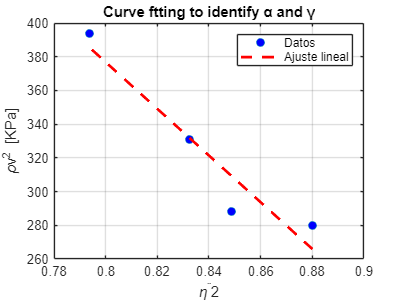


% Calcular valores ajustados
y_fit = polyval(p, x);

% Graficar
figure();
plot(x, y/1000, 'o', 'MarkerFaceColor', 'b'); hold on
plot(x, y_fit/1000, '--r', 'LineWidth', 2);
title('Curve ftting to identify α and γ')
legend('Datos', 'Ajuste lineal')
xlabel('\eta^¨2'); ylabel('\rhov^2 [KPa]');
grid on

% Resultados
alpha = b

alpha = 1.4853e+06

gamma = -m

gamma = 1.3857e+06


stress = alpha - gamma

stress = 9.9656e+04

strain = -1 + (alpha/gamma)^(1/3)

strain = 0.0234

young = stress/strain

young = 4.2552e+06